# Initialization

% initialization, assign the value of parameters
N = 110;
k = 10; % timestep
constantSpeed = 33;
me = 0; % mean of gauss function    
sigma = 1; % standard deviation of gauss function
a = 0;
b = 1;

# % call functions

generate function, particleFilter function and plotresult function

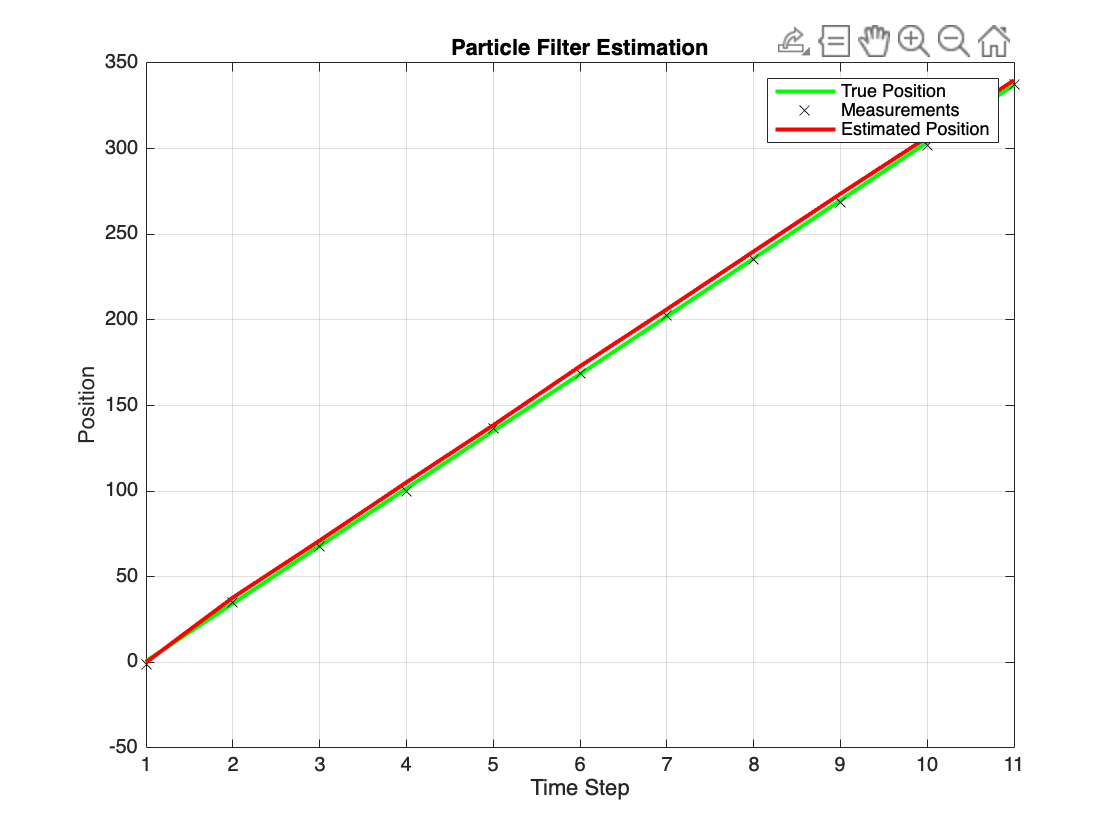

% call generate function
[x, z, i, sysNoise, measureNoise] = generate(k, constantSpeed);

% call Particle Filter function
[x_est, particles, weights] = ParticleFilter(z, constantSpeed, N, k, me, sigma, a, b);

% plot results
plotResults(x, z, x_est, i);

% call evaluatePerformance function
evaluatePerformance(x, x_est, weights, sigma);

Performance Metrics:
                    MSE: 11.9844
                   RMSE: 3.4618
                    MAE: 3.3272
               MaxError: 4.5728
    CoverageProbability: 0.0909
      ParticleDiversity: 0.6776
                   CRLB: 1



% MSE mean of (the difference between x and x_est)^2, 适用于：最小化大偏差至关重要的场景
% 由于平方操作，强调较大的误差。适用于那些特别不希望出现大误差的应用场景。
% MAE mean of (the difference between x and x_est)
% RMSE
% Max Error: 指示最坏情况下的误差
%
%



# store parameters in table

each parameter is a vector/ row

parameters = table;
parameters.i = i';
parameters.x = x';
parameters.z = z';
parameters.sysNoise = sysNoise';
parameters.measureNoise = measureNoise';
%parameters.pG = pG';
%parameters.pU = pU';

# %Store parameters in a table with cell arrays for matrices (reserve for later)

%parameters = table; parameters.i = {i}; % i as a row vector, stored in a cell parameters.x = {x'}; % x matrix transposed to fit the table, stored in a cell parameters.z = {z'}; % z matrix transposed to fit the table, stored in a cell parameters.sysNoise = {sysNoise'}; % sysNoise matrix transposed, stored in a cell parameters.measureNoise = {measureNoise'}; % measureNoise matrix transposed, stored in a cell parameters.pG = {pG'}; % pG matrix transposed to fit the table, stored in a cell parameters.pU = {pU'}; % pU matrix transposed to fit the table, stored in a cell access 提取z矩阵:

%
%zMatrix = parameters.z{1}; % 因为z存储在单元格中，使用{1}访问单元格内容
% 访问第10个粒子在时间步2的z值: zmatrix(i,idx)
%zValue = zMatrix(2, 10);
%如果您有 parameters.z{2}，这可能是因为：
%存储了不同的数据集：例如，如果您在相同的表格中存储了来自不同仿真场景的测量值，
% parameters.z{1} 可能包含第一组测量值，而 parameters.z{2} 包含第二组测量值。